% 读取图像
image = imread('olympic.jpg')

image = 426×426×3 uint8 数组
image(:,:,1) =

     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1   

% 设置参数：半径范围、圆心距离阈值、半径差异阈值
minRadius = 5;
maxRadius = 50;
distanceThreshold = 40;  % 圆心之间的最大距离
radiusThreshold = 20;     % 半径差异的最大值

% 调用findCircles函数，返回检测到的圆
circles = findCircles(image, minRadius, maxRadius, distanceThreshold, radiusThreshold);

% 输出检测到的圆
disp(circles);

   128   357     6
   171   326    12
   242   311    13
   272   344    13
    85   153    14
    30   225    17
   121   125    17
   322   227    19
   321   269    21
   270   167    39
   163   346    42
   234   227    45
   162   255    49
   222   188    50



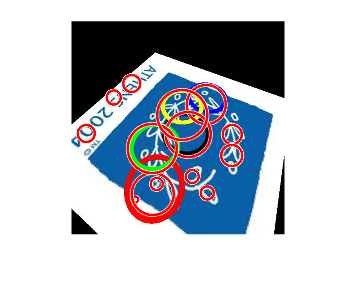


% 可视化检测结果
imshow(image);
hold on;
for i = 1:size(circles, 1)
    viscircles(circles(i, 1:2), circles(i, 3), 'EdgeColor', 'r');
end
saveas(gcf, 'olympic_result.png');
hold off;

% coins: 25 35 20 10
% colorChips: 15 30 10 10 
% olympic: 5 50 40 20
% pillsetc: 10 50 10 20
